# Three Node Network inversion with TAPAS

## Simulate resting state data for three node network

As done in Frässle et al. (2021) using function created code from SPM's `DEM_demo_induced_fMRI.m `to generate resting state time series.

stim_options = get_default_stim_options();

Generate data using AR(1) process.

[DCM, options] = make_DEM_demo_induced_fmri(stim_options);

Visualize simulated graph and BOLD data.

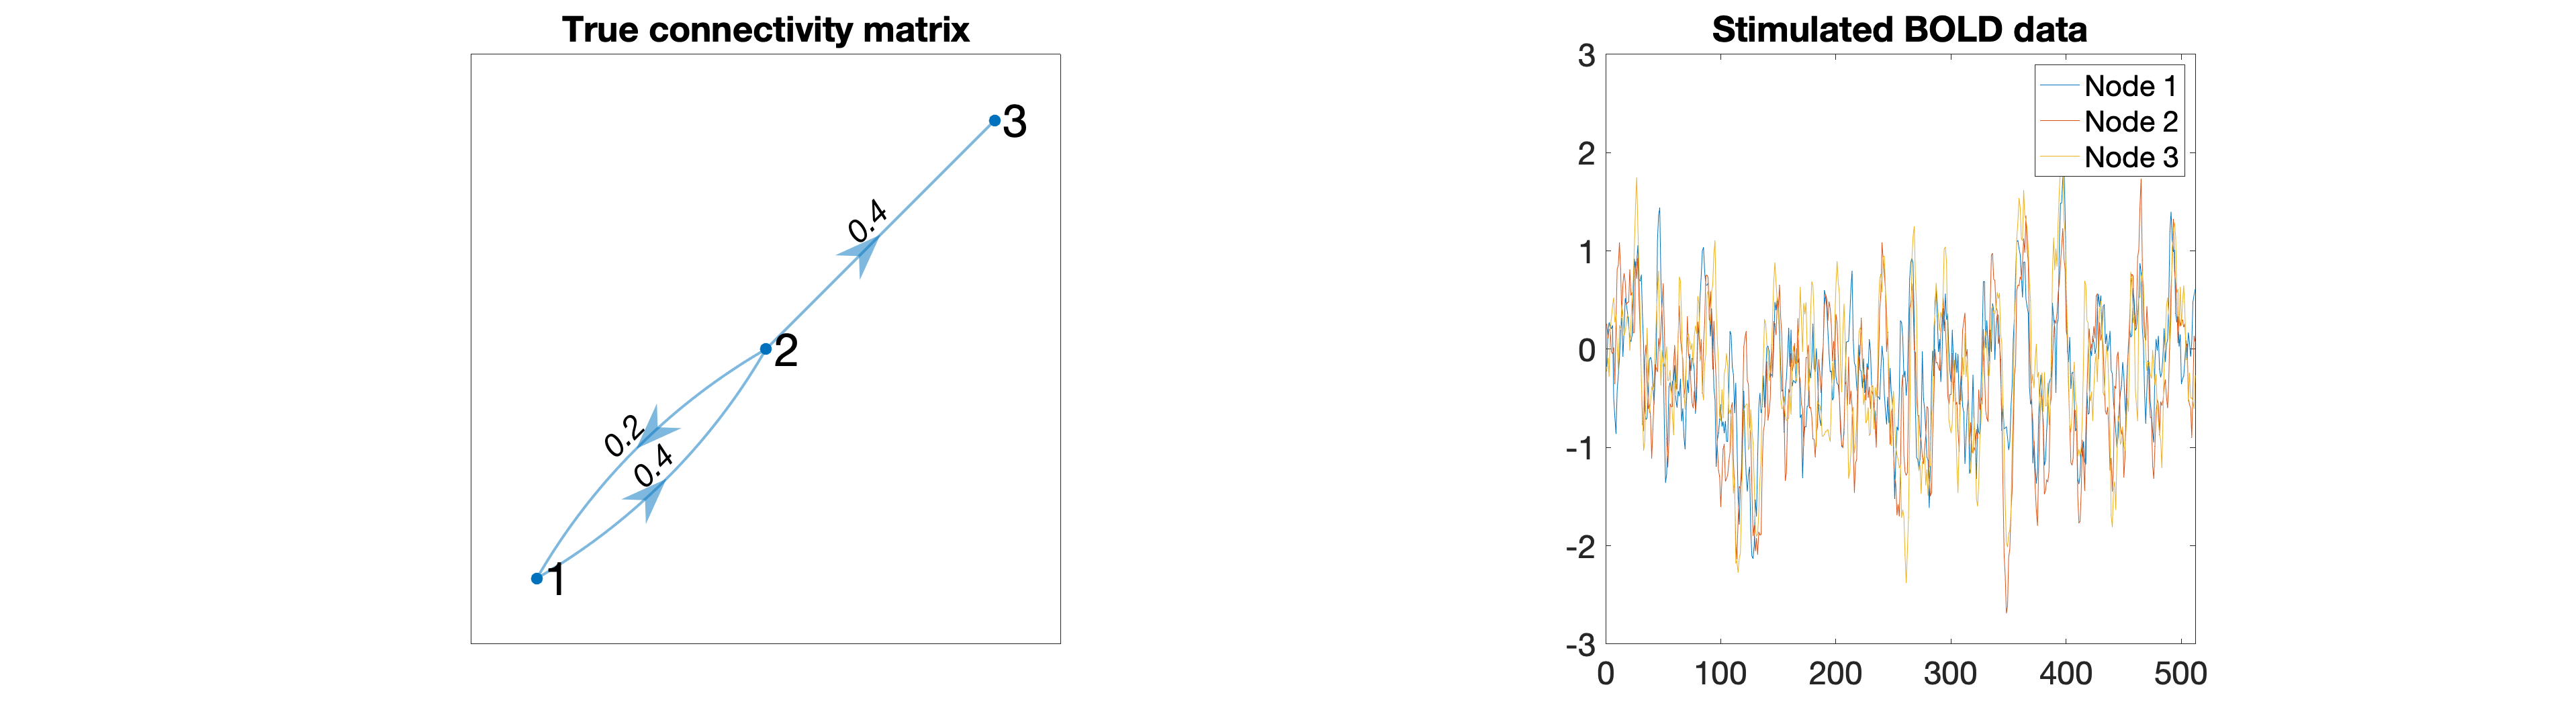

plot_sim_data(DCM)

Specify the options for the rDCM analysis

type = 'r'; % setting to 'r' instead of 's' until bug is fixed
methods = 1; %1 for ridge, 2 for pruning

## Invert simulated data

Remove input so rDCM knows its endogenous activity and set other parameters in the structure that the functions need.

--> Makes no difference for ridge regression.

 DCM = rmfield(DCM,'U');
[output, options] = tapas_rdcm_estimate(DCM, type, options, methods);


Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


output.Ep.A

ans =    -0.2876    0.1135    0.0355
    0.1722   -0.2937    0.1088
    0.0580    0.1697   -0.2803


Does it make a difference for sparse regression?

**--> No difference for sparse regression estimates of A either after removing the input U from the DCM structure.**

[output, options] = tapas_rdcm_estimate(DCM, type, options, 2);


Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results


output.Ep.A

ans =    -0.0695         0         0
         0   -0.0520         0
         0         0   -0.0556


Any more successful in recovering A if I kept the original pP.A from DEM_demo_induced_fmri.

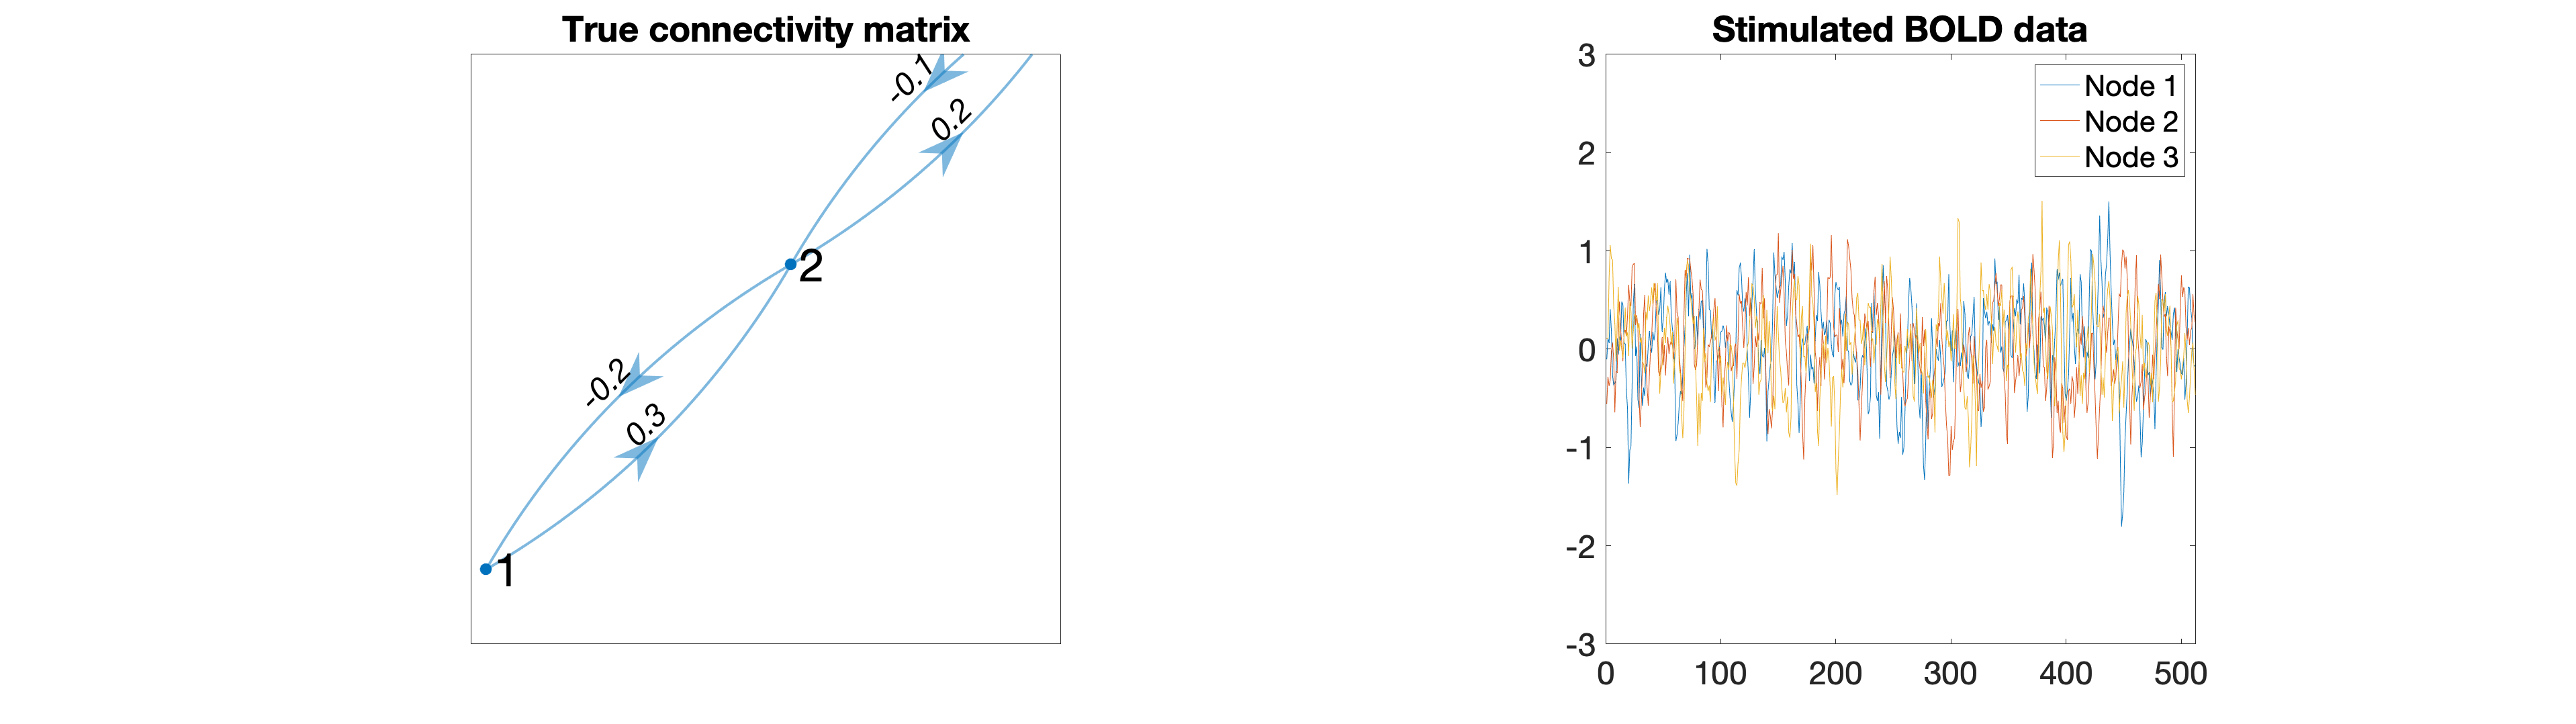

stim_options = rmfield(stim_options,'Tp');
[DCM, options] = make_DEM_demo_induced_fmri(stim_options);
plot_sim_data(DCM)

[output, options] = tapas_rdcm_estimate(DCM, type, options, methods);


Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


output.Ep.A

ans =    -0.2853   -0.0335   -0.0004
    0.0546   -0.2911   -0.0302
   -0.0156    0.0511   -0.3077


Any better with original pP.A and sparse?

[output, options] = tapas_rdcm_estimate(DCM, type, options, 2);


Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results


output.Ep.A

ans =    -0.1204         0         0
         0   -0.1276         0
         0         0   -0.1417


What if DCM.a is not fully connected but set to logical(pP.A)?

stim_options = rmfield(stim_options,'a');
[DCM, options] = make_DEM_demo_induced_fmri(stim_options);
[output, options] = tapas_rdcm_estimate(DCM, type, options, methods);


Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


output.Ep.A

ans =          0   -0.0463         0
    0.0461         0   -0.0207
         0    0.0160         0


## Gotta understand

- How DCM.a and DCM.c are used in estimation. Are they priors? -> hard boundaries for what is estimated. 

- difference between ridge and sparse regressions in rDCM -> need to re-read Frässle et al. (2018)